## DUTY 70%

meas70 = [199.5 199.8 199.8 199.9 200.0 200.0 200.0 200.0 200.0 200.0 200.0 199.9 200.0 200.0 200.0];

## DUTY 65%

meas65 = [187.2 187.1 187.7 187.3 187.3 186.5 187.4 186.6 187.4 187.4 187.1 186.4 188.6 187.2 187.2];

## DUTY 60%

meas60 = [176.7 177.1 176.9 177.0 177.0 177.0 176.6 177.1 176.6 176.3 175.7 176.0 176.2 176.0 176.2];

## DUTY 55%

meas55 = [173.5 172.9 174.3 174.2 173.8 174.2 173.8 173.9 173.8 174.2 174.3 173.7 174.5 173.8 174.1];

## DUTY 50%

meas50 = [172.2 172.3 172.2 172.6 172.6 172.5 172.5 172.3 172.4 172.1 172.5 172.0 172.3 172.1 172.0];

## DUTY 45%

meas45 = [164.1 164.0 163.0 162.5 163.5 163.0 163.5 163.3 163.0 162.8 161.8 162.9 163.0 162.3 162.6];

## DUTY 35%

meas35 = [144.8 144.7 144.9 145.1 144.9 143.9 143.9 144.4 144.3 143.6 143.7 144.4 143.2 143.6 143.8];

## Behandling

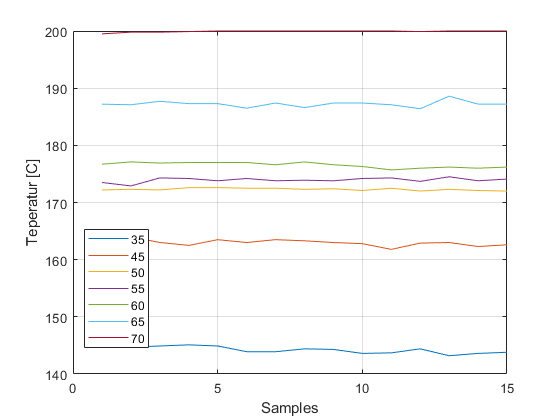

figure('name','stady temp over time');
plot(meas35);
hold on;
grid on;
plot(meas45);
plot(meas50);
plot(meas55);
plot(meas60);
plot(meas65);
plot(meas70);
hold off;
legend('35','45','50','55','60','65','70','location',"best");
xlabel('Samples');
ylabel('Teperatur [C]');


m35 = mean(meas35)

m35 = 144.2133

m45 = mean(meas45)

m45 = 163.0200

m50 = mean(meas50)

m50 = 172.3067

m55 = mean(meas55)

m55 = 173.9333

m60 = mean(meas60)

m60 = 176.5600

m65 = mean(meas65)

m65 = 187.2267

m70 = mean(meas70)

m70 = 199.9267

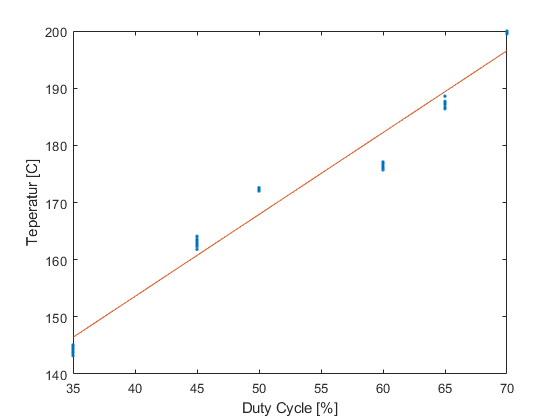


allData = [meas35(:);meas45(:);meas50(:);meas60(:);meas65(:);meas70(:)];
allDuty = [ones(length(meas35),1)*0.35;ones(length(meas45),1)*0.45;ones(length(meas50),1)*0.50;ones(length(meas60),1)*0.60;ones(length(meas65),1)*0.65;ones(length(meas70),1)*0.7]*100;

figure('name','Temp over duty-cycle');
DUTY_TEMP = [mean(meas35) mean(meas45) mean(meas50) mean(meas55) mean(meas60) mean(meas65) mean(meas70)];
X = [0.35 0.45 0.50 0.55 0.60 0.65 0.70]*100;
plot(allDuty,allData,'.');
[a,b] = lineFit(allDuty,allData);
hold on;
plot(X,a*X+b);

xlabel('Duty Cycle [%]');
ylabel('Teperatur [C]');

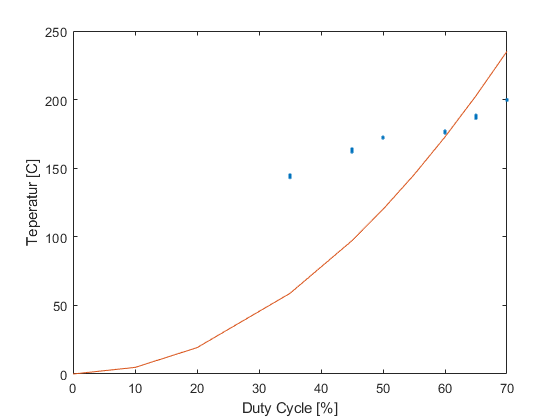

figure('name','Temp over duty-cycle');
DUTY_TEMP = [mean(meas35) mean(meas45) mean(meas50) mean(meas55) mean(meas60) mean(meas65) mean(meas70)];
X = [0, 0.1, 0.2, 0.35 0.45 0.50 0.55 0.60 0.65 0.70]*100;
plot(allDuty,allData,'.');
hold on;
plot(X,((X.^2)*(240^2))/1200000);

xlabel('Duty Cycle [%]');
ylabel('Teperatur [C]');